# BD & EIGENVALUEs

In this example, we will desmonstrate how to utilize the eigenvalues of a bifurcation diagram generated using XPPAUT. Specifically, we will show

- How to visualize the eigenvalues of a one-parameter bifurcation diagram

- How to access the eigenvalues (for your own use)

**!! **We strongly urge the user to run the demonstrations of the *Func_VisualizeEig* code sections in the corresponding `.m` file as the interactive 3-dimensional plots within the live editor are slow and may lead Matlab to crash. **!!**

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% IMPORT
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

The first operation consists of reading the model. For this reason, we use the function *Func_ReadModel *to extract the necessary information.

% MODEL
M = Func_ReadModel('hh.ode');

## AUTORePO

We load the file `hh.auto` by using the function *Func_ReadDiagram*. As it could be seen by executing the following chunk of code, the `.auto` file stores two bifurcation diagrams. These two are saved, as seen in past examples, as fields of the structure `AR`. Their names are

- `BD1_i0`: It is a 1P-BD computed by using as main bifurcation parameter the applied current `i0`.

- `BD2_i0_gk`: This is a 2P-BD where the main bifurcation parameter is `i0`, while the second bifurcation parameter is `gk`.

For more information on this function, please see *DEMO1_HH_MDL*.

% AUTOREPO
AR = Func_ReadAutoRepo(M,'hh.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_i0 - Main: i0
        2P-BD - Name: BD2_i0_gk - Main: i0 - Secondary: gk


## 1-PAR BD VISUALIZATION

Recall (from *DEMO_HH_MDL*) that we can visualize a 1-parameter bifurcation diagram using *Func_VisualizeDiagram *and *Func_VisualizeLabPoints* for the labeled points.

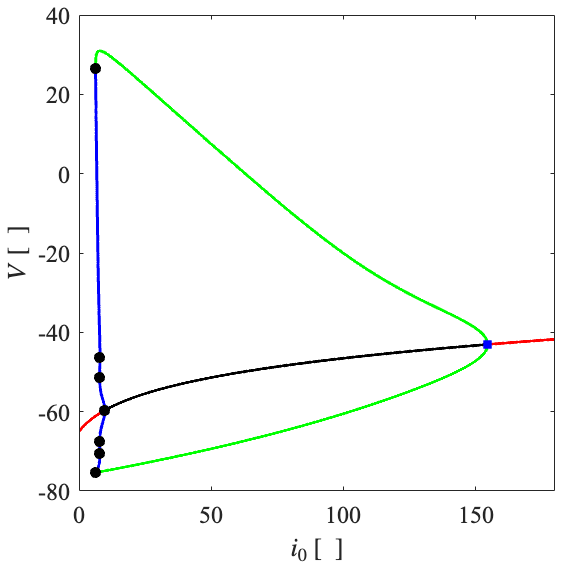

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD1_i0)
Func_VisualizeLabPoints(M,AR.BD1_i0)

xlabel('$i_0$ [\ ]','interpreter','latex'), xlim([0  180])
ylabel('$V$ [\ ]','interpreter','latex')  , ylim([-80 40])

Func_FigStyle(fig)

## EIGENVALUE VISUALIZATION

Now we would like to inspect the eigenvalues along the branches of the 1-parameter bifurcation diagram. We can do this by using the function *Func_VisualizeEig *which takes as arguments:

- **M**: Model structure.

- **BD**: Bifurcation diagram structure to be visualized.

- [VAR]: Cell vector of maximum three elements. Here the variables/parameters to be visualized along the *x*, *y* and eventually *z* direction must be specified. Defaults to the first dynamical variable and bifurcation parameter.

- [BRIND]: Cell array of branch indices to be visualized. Defaults to all branches within BD.

- [TYPE]: Specifies if real or imaginary parts of eigenvalues are to be visualized. Defaults to real parts.

- [OPTIONs]: Visualization setting structure. If you want to costumize your visualization settings instead of using the default ones, then create your own `opts` structure and specify it here. Defaults to an XPPLORE default visualization specifications.

In the example below, we will pass the variable **M** as first, and **AR.BD1_i0** as the second input argument. The optionals fields VAR, BRIND, TYPE and OPTIONs must be specified as name-value pair arguments. We will visualize a 1P-BD, by default the first dynamical variable specified in the `.ode` file (here V) with respect to the main bifurcation parameter `i0`. The function call below visualizes both the branches of the specified bifurcation diagram an the labeled points for 

- Re(Eig) = 0: same `BD` as the one that is plotted by using *Func_VisualizeDiagram* with *Func_VisualizeLabPoints,*

- the BD with Re(Eig) for the number of dimensions of the system (here: 4). These branches have the same color coding as the BD in the Re(Eig)=0 plane.

NOTE: For every point, the real parts of the eigenvalues are sorted, and then the imaginary components are arranged in the same order so that the Re-Im eigenvalue pairs remain intact. Then, the points within a branch are connected as one "continuous" branch of the largest real part eigenvalues along that branch, another with all of the second largest real part eigenvalues, and so on.

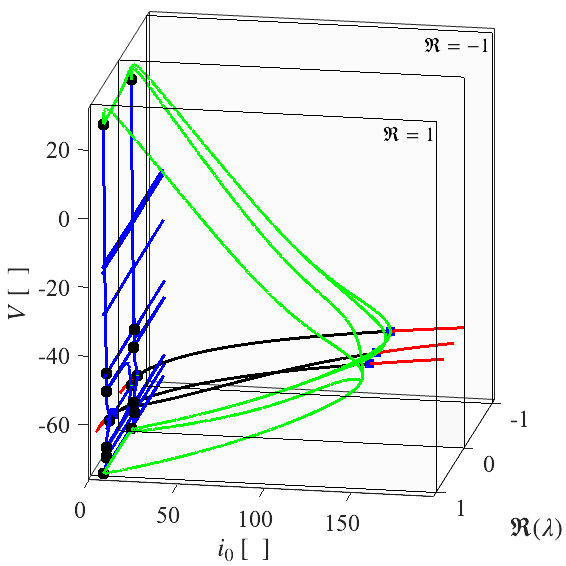

opts = Func_DOF('ClippingStyle','3dbox');

% VISUALIZATION
fig = figure();

Func_VisualizeEig(M,AR.BD1_i0)

xlabel('$i_0$ [\ ]','interpreter','latex')
ylabel('$\Re(\lambda)$','interpreter','latex')
zlabel('$V$ [\ ]','interpreter','latex')

Func_FigStyle(fig,'OPTIONs',opts)

We can see that this function automatically plots the planes at `Re` or `Im(eig)= -1, 0, 1` to see where the BD branches with nonzero eigenvalues cross each plane. 

We can also specify a subset of branch indices within `AR.BD1_i0.BR` as shown below. This optional argument must be specified as a name-value pair (e.g. 'BRIND', {1,2,3}). Inspecting `AR.BD1_i0.BR `has a total of 10 branches.

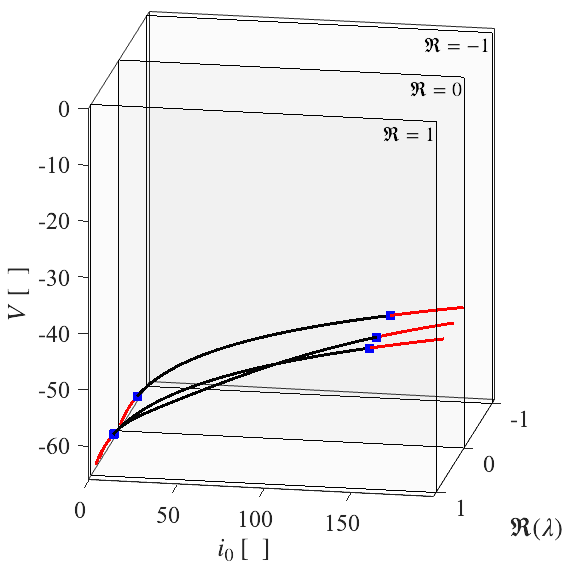

% VISUALIZATION
fig = figure();

Func_VisualizeEig(M,AR.BD1_i0,'BRIND',{1,2,3,4})

xlabel('$i_0$ [\ ]','interpreter','latex')
ylabel('$\Re(\lambda)$','interpreter','latex')
zlabel('$V$ [\ ]','interpreter','latex')
Func_FigStyle(fig,'OPTIONs',opts)

In AUTO, labeled points are saved and assigned to one branch of the bifurcation diagram. Because of this, if one of the Andronov-Hopf bifurcations in the above figure (blue labeled points) lies on a branch which is removed, this labeled point will be removed as well.

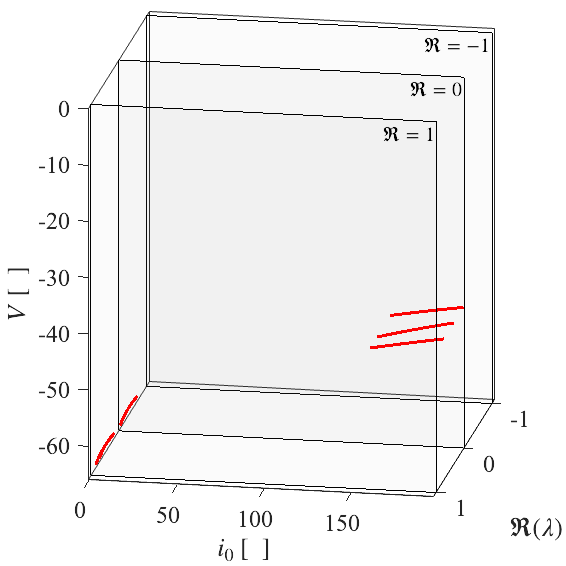

% VISUALIZATION
fig = figure();

Func_VisualizeEig(M,AR.BD1_i0,'BRIND',{1,2,4})

xlabel('$i_0$ [\ ]','interpreter','latex')
ylabel('$\Re(\lambda)$','interpreter','latex')
zlabel('$V$ [\ ]','interpreter','latex')

Func_FigStyle(fig,'OPTIONs',opts)

Lastly, we can visualize the imaginary components of the eigenvalues by specifying the TYPE argument.

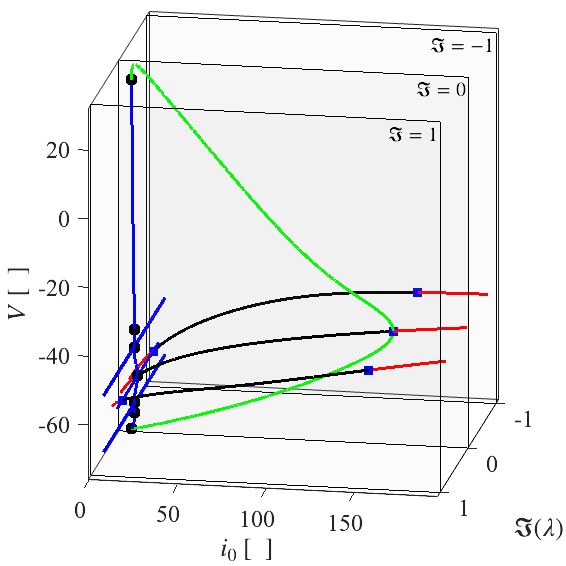

% VISUALIZATION
fig = figure();

Func_VisualizeEig(M,AR.BD1_i0,'TYPE','Im')

xlabel('$i_0$ [\ ]','interpreter','latex')
ylabel('$\Im(\lambda)$','interpreter','latex')
zlabel('$V$ [\ ]','interpreter','latex')

Func_FigStyle(fig,'OPTIONs',opts)

## RETRIEVING EIGENVALUES

Another way to inspect the eigenvalues of a 1-parameter bifurcation diagram is the function *Func_GetEig*. This function is mainly utilized by the visualization using *Func_VisualizeEig*, but it is also accessible to the user. The function takes the following arguments:

- **BD**: Bifurcation diagram structure to be visualized

- [SORTED]: true/false. Determines if the eigenvalues at each point should be sorted with respect to the real components of the eigenvalues or not at all. The default boolean value is 'true'. 

This function returns:

- EIG: A struct containing, by branch, all of the points within the specified BD. The eigenvalues can be accessed using EIG{branch}(pt_num, i, 1(Re) or 2(Im)) where **branch** is the index of the branch, **pt_num** is the number of the point along that branch,** i **is the index (between 1 and the dimension of the system) and **1 **refers to the real part and **2** to the imaginary part of the eigenvalues.

- EIGLAB: Similar to EIG, this 3-dimensional matrix consists of (point_ind, i, 1(Re) or 2(Im)). However, here, **i** is the index between 1 and 1+dim. system. When i=1, the entry will represent the corresponding branch number.

The example below retrieves the eigenvalues of the branches and labeled points within `AR.BD1_i0`.

[EIG, EIGLAB] = Func_GetEig(AR.BD1_i0);

The below code accesses the 5th point within the 2nd branch of the bifurcation diagram, the real parts ("1") of all 4 (":") eigenvalues.

EIG{2}(5,:,1)

ans =     0.0093    0.7574    0.7574    0.8863


This code accesses the branch index (here: 3) as well as the imaginary ("2") components of all 4 eigenvalues of the 3rd labeled point.

EIGLAB(3,:,2)

ans =     3.0000         0    0.8738   -0.8738         0
